# Test AWPs mit mehreren unbekannten Funktionen

clear

## Funktion F gibt Spaltenvektor zurück

F = @(x, y) check(y) * [
    -y(1) + y(2) + cos(4*x)
     y(1) - y(2)
];

Euler

[x, ye] = euler(F, [0, 5], 0.1, [-1; 1]);

Halbschritt

[~, yh] = halbschritt(F, [0, 5], 0.1, [-1; 1]);

Runge-Kutta

[~, yrk] = rungekutta(F, [0, 5], 0.1, [-1; 1]);

Plot

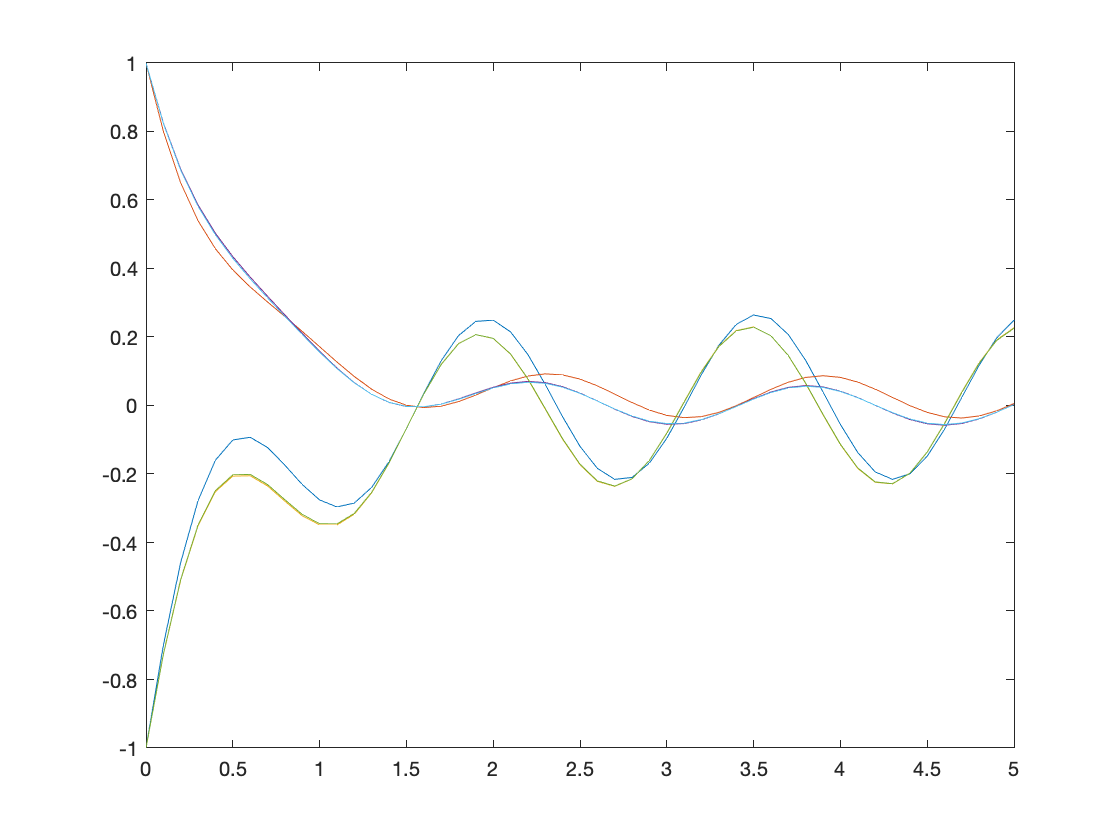

plot(x, ye, x, yh, x, yrk)

## Funktion F gibt Zeilenvektor zurück

F = @(x, y) [-y(1) + y(2) + cos(4*x) y(1) - y(2)];

Euler

[x, ye] = euler(F, [0, 5], 0.1, [-1; 1]);

Halbschritt

[~, yh] = halbschritt(F, [0, 5], 0.1, [-1; 1]);

Runge-Kutta

[~, yrk] = rungekutta(F, [0, 5], 0.1, [-1; 1]);

Plot

plot(x, ye, x, yh, x, yrk)

## Prüfen ob Spaltenvektor übergeben wurde

function a = check(y)
    if size(y, 2) ~= 1
        error('Kein Spaltenvektor!');
    end
   a = 1; 
end